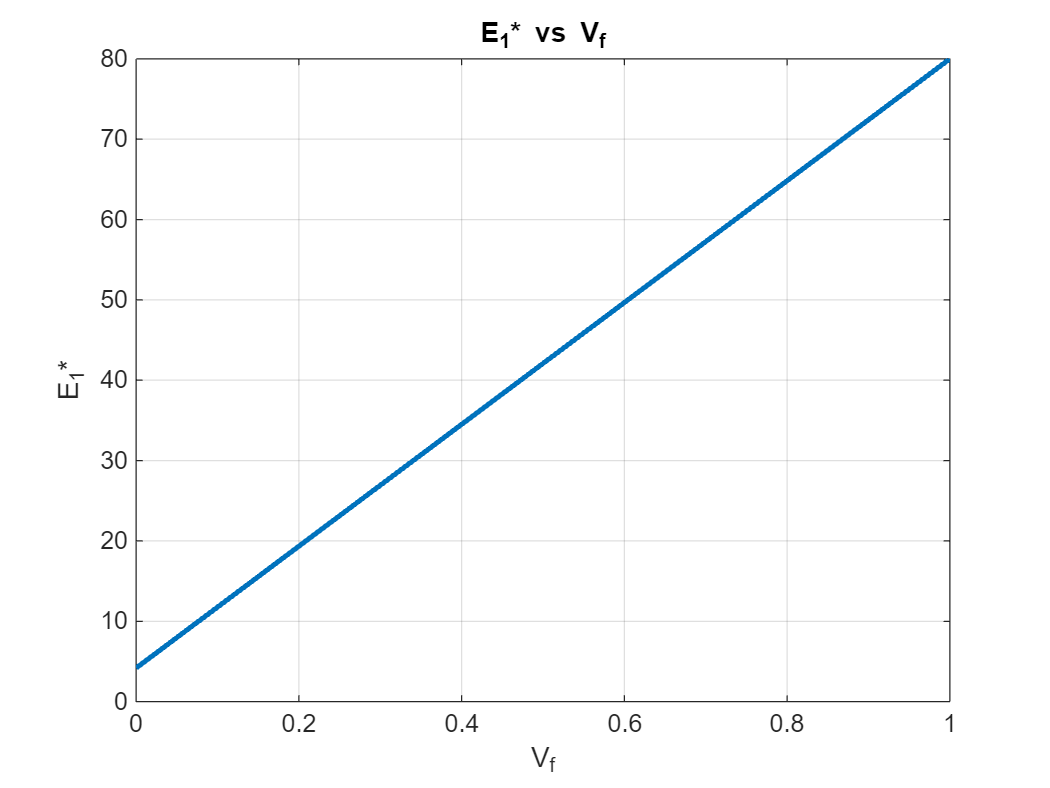

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;

S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
G_m = E_m/(2*(1+v_m));

S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

% fiber
syms n_f m_f k_f l_f p_f
eqn1 = n_f == C_f(1,1);
eqn2 = l_f == C_f(1,2);
eqn3 = k_f + m_f == C_f(2,2);
eqn4 = m_f == C_f(4,4);
eqn5 = p_f == C_f(5,5);

fiber = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_f,l_f,k_f,m_f,p_f]);
n_f = fiber.n_f;
m_f = fiber.m_f;
k_f = fiber.k_f;
l_f = fiber.l_f;
p_f = fiber.p_f;

% matrix
syms n_m m_m k_m l_m p_m
eqn1 = n_m == C_m(1,1);
eqn2 = l_m == C_m(1,2);
eqn3 = k_m + m_m == C_m(2,2);
eqn4 = m_m == C_m(4,4);
eqn5 = p_m == C_m(5,5);

matrix = solve([eqn1,eqn2,eqn3,eqn4,eqn5],[n_m,l_m,k_m,m_m,p_m]);
n_m = matrix.n_m;
m_m = matrix.m_m;
k_m = matrix.k_m;
l_m = matrix.l_m;
p_m = matrix.p_m;

zeta = 2;

eta_1 = ((k_f/k_m) - 1) / ((k_f/k_m) + zeta);
k_c = k_m * ((1 + zeta * eta_1 * Vf) / (1 - eta_1 * Vf));

eta_2 = ((l_f/l_m) - 1) / ((l_f/l_m) + zeta);
l_c = l_m * ((1 + zeta * eta_2 * Vf) / (1 - eta_2 * Vf));

eta_3 = ((m_f/m_m) - 1) / ((m_f/m_m) + zeta);
m_c = m_m * ((1 + zeta * eta_3 * Vf) / (1 - eta_3 * Vf));

eta_4 = ((n_f/n_m) - 1) / ((n_f/n_m) + zeta);
n_c = n_m * ((1 + zeta * eta_4 * Vf) / (1 - eta_4 * Vf));

eta_5 = ((p_f/p_m) - 1) / ((p_f/p_m) + zeta);
p_c = p_m * ((1 + zeta * eta_5 * Vf) / (1 - eta_5 * Vf));

C_c = [n_c, l_c, l_c, 0, 0, 0;
       l_c, k_c+m_c, k_c-m_c, 0, 0, 0;
       l_c, k_c-m_c, k_c+m_c, 0, 0, 0;
       0, 0, 0, m_c, 0, 0;
       0, 0, 0, 0, p_c, 0;
       0, 0, 0, 0, 0, p_c;];

S_c = inv(C_c);

%E1
E1_c = Vf * E_f + (1 - Vf) * E_m;
E1_c_val = double(subs(E1_c,Vf_val));

%E2
E2_c = 1/S_c(2,2);
E2_c_val = double(subs(E2_c,Vf_val));

%v12
v12_c = Vf * v_f + (1 - Vf) * v_m;
v12_c_val = double(subs(v12_c,Vf_val));

%v23
v23_c = -S_c(3,2)*E2_c;
v23_c_val = double(subs(v23_c,Vf_val));

%G12
G12_c = 1/S_c(5,5);
G12_c_val = double(subs(G12_c,Vf_val));

%G23
G23_c = 1/S_c(4,4);
G23_c_val = double(subs(G23_c,Vf_val));

%plot
figure;
plot(Vf_val, E1_c_val, 'LineWidth', 2);
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
grid on;

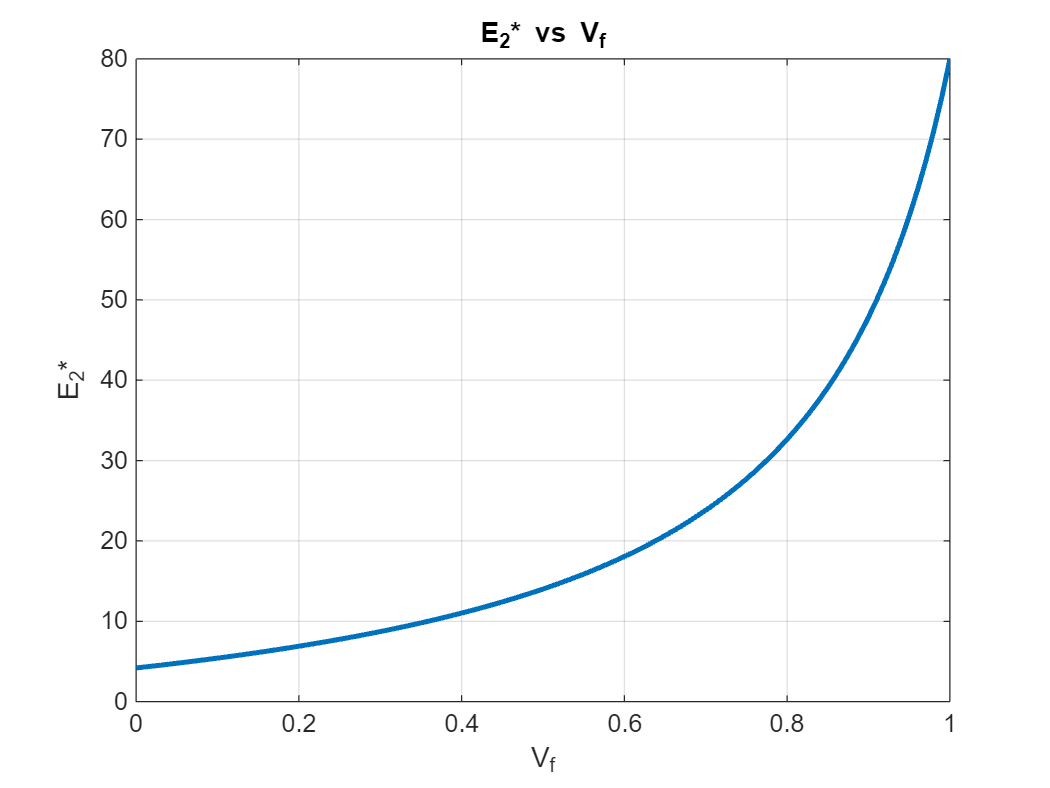


figure;
plot(Vf_val, E2_c_val, 'LineWidth', 2);
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
grid on;

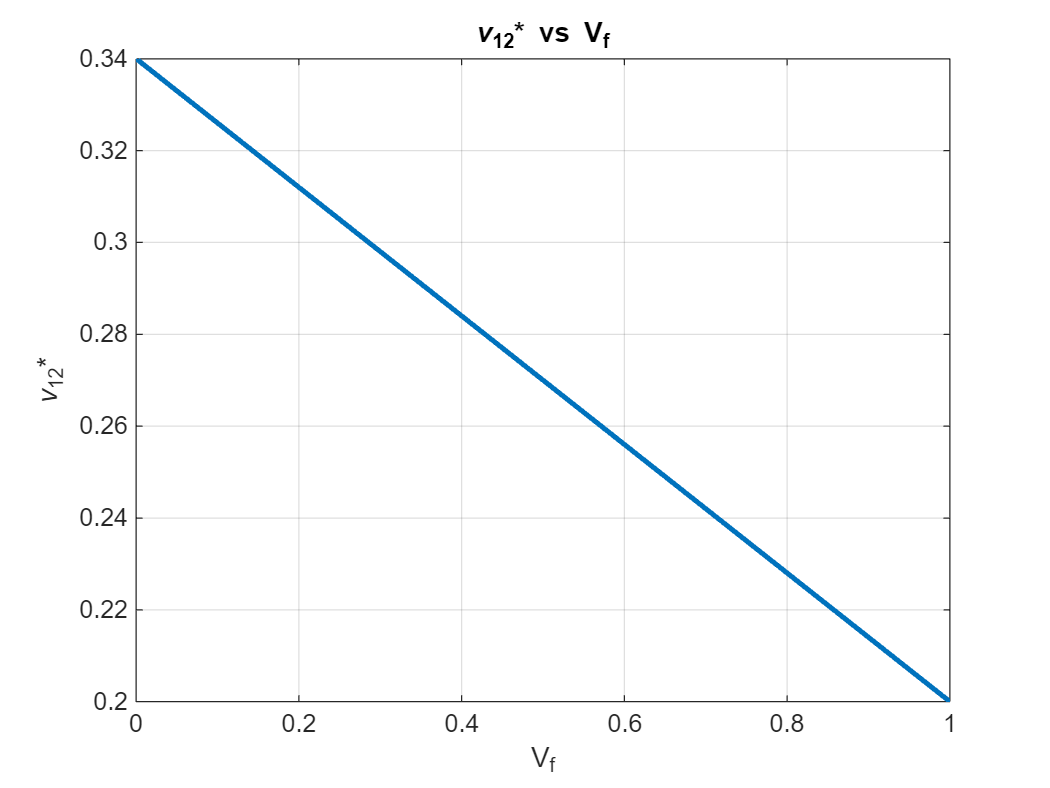


figure;
plot(Vf_val, v12_c_val, 'LineWidth', 2);
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
grid on;

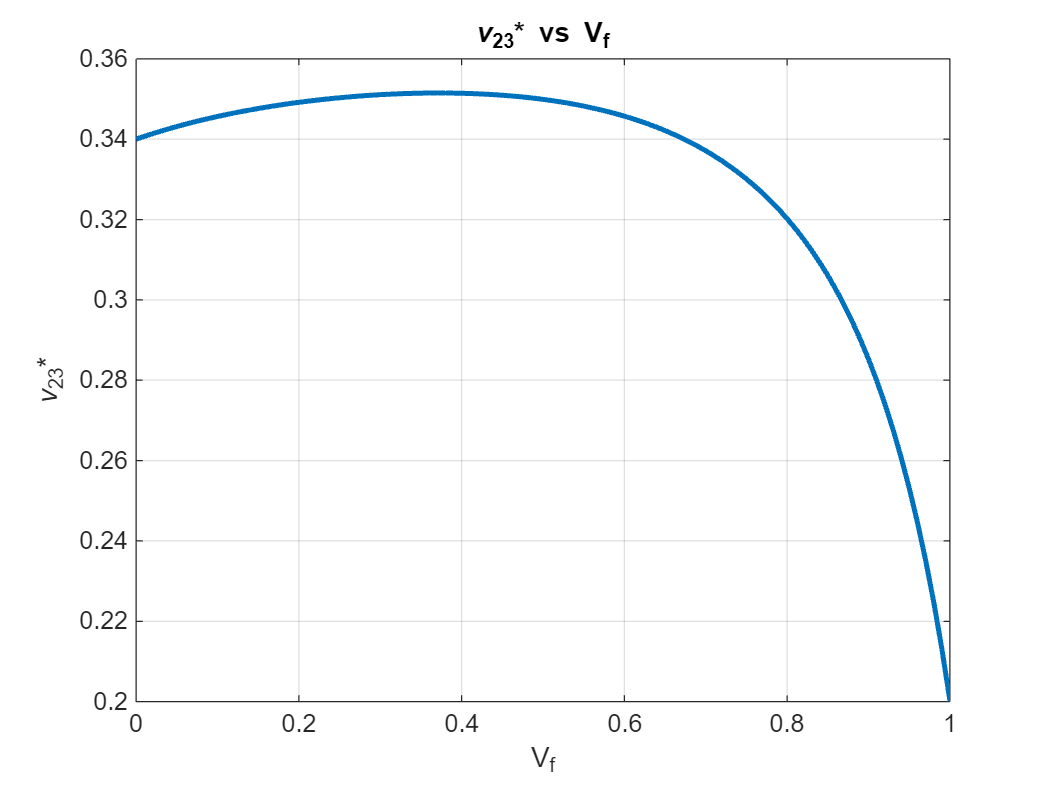


figure;
plot(Vf_val, v23_c_val, 'LineWidth', 2);
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
grid on;

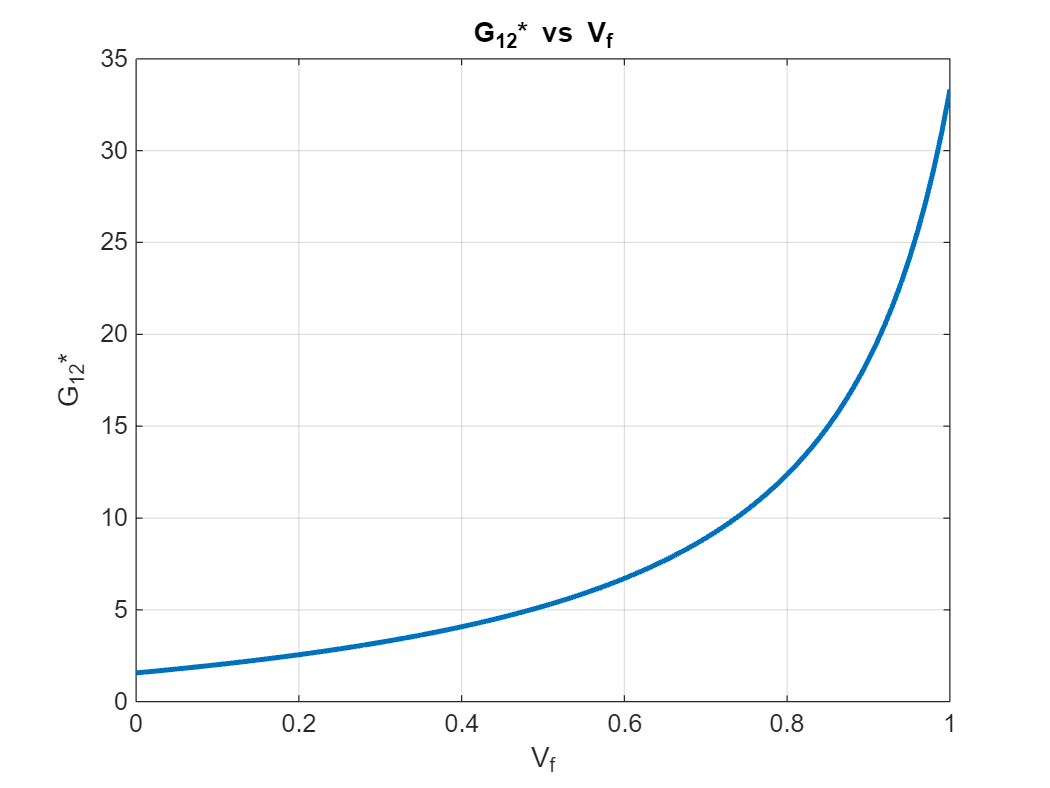


figure;
plot(Vf_val, G12_c_val, 'LineWidth', 2);
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
grid on;

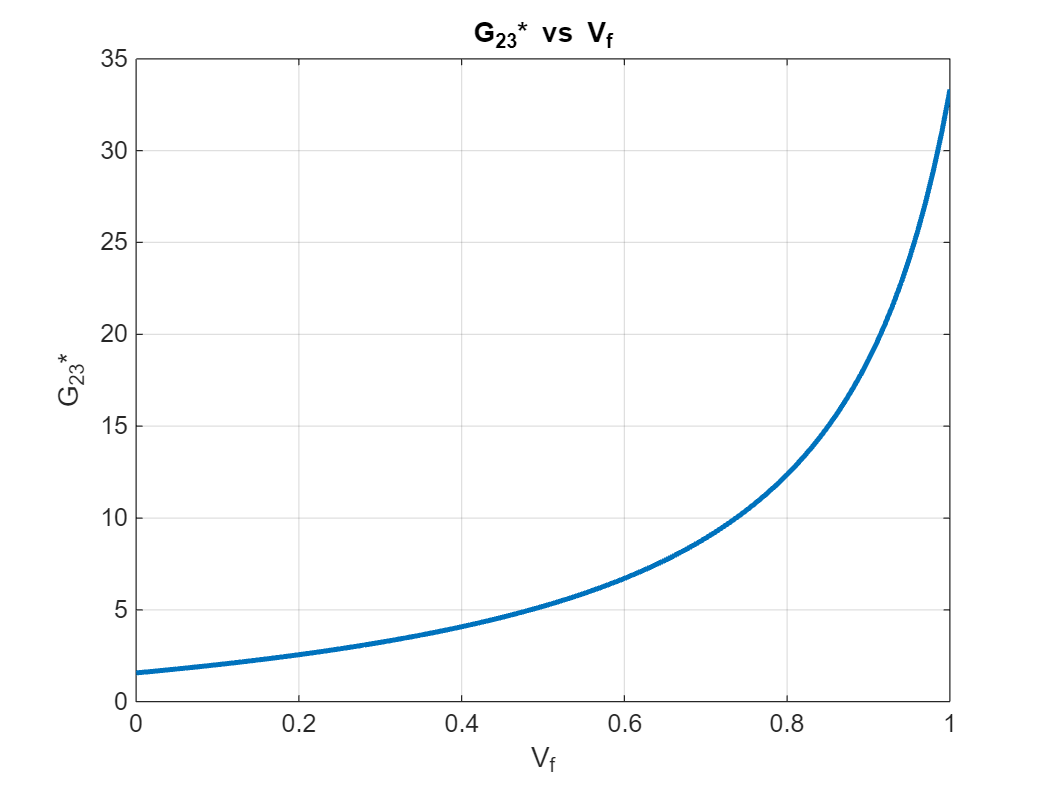


figure;
plot(Vf_val, G23_c_val, 'LineWidth', 2);
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
grid on;